clear all;clc;

## Load or specify category labels

addpath(genpath('./matlab_functions'))

d = natsortfiles(dir(['./behaviorData/shrewData.mat']));
load([d(end).folder,'/',d(end).name])

exp_colors = flipud([179,128,206;...
    211,107,172;...
    254,153,132;...
    248,214,86]/256);

trial_colors = [62,159,44;...
    14,144,201;...
    30,57,155]/256;


## Manipulate data

displayNSess = false;

% Determine which shrews to use
shrewname={'Seymour','Dominic','Ryker'};
shrewID = 1:3;

allTasks = {'Camel_v2_test_nn','Camel_novel_v2_test_nn','Camel_Rhino_test_nn','Camel_background_matrix'};

sessionNTrials = cell(length(allTasks),length(shrewname));
sessionNTarg = cell(length(allTasks),length(shrewname));
sessionAcc_Catch = cell(1,length(allTasks));
sessionAcc_nonCatch = cell(1,length(allTasks));
sessionAcc_test = cell(1,length(allTasks));
sessionAcc_NovUnrew = cell(1,length(allTasks));
sessionAcc_NovRew = cell(1,length(allTasks));
sessionPerf_NovUnrew = cell(1,length(allTasks));
sessionPerf_NovRew = cell(1,length(allTasks));
sessionAcc_NovTarg = cell(1,length(allTasks));
sessionAcc_NovDist = cell(1,length(allTasks));
sessionAcc_NovBoth = cell(1,length(allTasks));
sessionAcc_Familiar = cell(1,length(allTasks));
targPerf = cell(length(allTasks),length(shrewname));
targPerf_train = cell(length(allTasks),length(shrewname));
targPerf_trainID = cell(length(allTasks),length(shrewname));
targPerf_test = cell(length(allTasks),length(shrewname));
targPerf_split1 = cell(length(allTasks),length(shrewname));
targPerf_split2 = cell(length(allTasks),length(shrewname));
targPerf_test_split1 = cell(length(allTasks),length(shrewname));
targPerf_test_split2 = cell(length(allTasks),length(shrewname));
targPerf_train_split1 = cell(length(allTasks),length(shrewname));
targPerf_train_split2 = cell(length(allTasks),length(shrewname));

for task = 1:length(allTasks)
    nTarg = length(unique(allData.(allTasks{task}).T_Expt_ID));
    
    targID = unique(allData.(allTasks{task}).T_Expt_ID);
    for ts = 1:length(shrewname)
        sessionIdx = unique(allData.(allTasks{task}).SessionID(allData.(allTasks{task}).ShrewID==ts));
        sessionNTrials{task,ts} = zeros(1,length(sessionIdx));
        sessionNTarg{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_Catch{task}{ts} = zeros(1,length(sessionIdx));
        sessionAcc_nonCatch{task}{ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovUnrew{task}{ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovRew{task}{ts} = zeros(1,length(sessionIdx));
        sessionPerf_NovUnrew{task}{ts} = {};
        sessionPerf_NovRew{task}{ts} = {};
        sessionAcc_NovTarg{task}{ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovDist{task}{ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovBoth{task}{ts} = zeros(1,length(sessionIdx));
        sessionAcc_test{task}{ts} = zeros(1,length(sessionIdx));
        sessionAcc_Familiar{task}{ts} = zeros(1,length(sessionIdx));
        
        catchTrials = allData.(allTasks{task}).ctch == 1;
        noncatchTrials = allData.(allTasks{task}).ctch ~= 1;
        novUnrewTrials = isnan(allData.(allTasks{task}).ctch);
        novTargTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0;
        novDistTrials = (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0;
        novBothTrials = ((allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 & (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0) |...
            ((allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).TestTarg)==0 & (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).TestDist)==0);
        anyNovTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0 |...
            (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).TestTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).TestDist)==0;
        novRewTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0;
        famTrials = ~anyNovTrials & ~catchTrials;
        
        if displayNSess
            disp([allTasks{task},', ',shrewname{ts},', NTarg = ',num2str(length(unique(allData.(allTasks{task}).T_Expt_ID(allData.(allTasks{task}).ShrewID==ts))))])
            disp([allTasks{task},', ',shrewname{ts},', NDist = ',num2str(length(unique(allData.(allTasks{task}).D_Expt_ID(allData.(allTasks{task}).ShrewID==ts))))])
        end
        
        for ss = 1:length(sessionIdx)
            sessionAcc_Catch{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & catchTrials),'omitnan');
            sessionAcc_nonCatch{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & noncatchTrials),'omitnan');
            sessionAcc_NovUnrew{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novUnrewTrials),'omitnan');
            sessionAcc_NovRew{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novRewTrials),'omitnan');
            sessionAcc_NovTarg{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novTargTrials),'omitnan');
            sessionAcc_NovDist{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novDistTrials),'omitnan');
            sessionAcc_NovBoth{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novBothTrials),'omitnan');
            sessionAcc_Familiar{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & famTrials),'omitnan');
            sessionNTrials{task,ts}(ss) = sum(allData.(allTasks{task}).SessionID==sessionIdx(ss));
            sessionNTarg{task,ts}(ss) = length(unique(allData.(allTasks{task}).T_Expt_ID(allData.(allTasks{task}).SessionID==sessionIdx(ss))));
            
            sessionPerf_NovUnrew{task}{ts}{ss} = allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novUnrewTrials);
            sessionPerf_NovRew{task}{ts}{ss} = allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novRewTrials);
        end
        
        for tt = 1:nTarg
            ntrials = sum(allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt));
            targPerf{task,ts}(tt) = nan;
            targPerf_train{task,ts}(tt) = nan;
            targPerf_trainID{task,ts}(tt) = nan;
            targPerf_test{task,ts}(tt) = nan;
            targPerf_split1{task,ts}(tt,:) = nan(1,1000);
            targPerf_split2{task,ts}(tt,:) = nan(1,1000);
            targPerf_test_split1{task,ts}(tt,:) = nan(1,1000);
            targPerf_test_split2{task,ts}(tt,:) = nan(1,1000);
            targPerf_train_split1{task,ts}(tt,:) = nan(1,1000);
            targPerf_train_split2{task,ts}(tt,:) = nan(1,1000);
            if ntrials >= 10
                inclusion = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt);
                targPerf{task,ts}(tt) = mean(allData.(allTasks{task}).correct(inclusion),'omitnan');
                inclusion_test = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & novBothTrials;
                targPerf_test{task,ts}(tt) = mean(allData.(allTasks{task}).correct(inclusion_test),'omitnan');
                inclusion_train = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & famTrials;
                targPerf_train{task,ts}(tt) = mean(allData.(allTasks{task}).correct(inclusion_train),'omitnan');
                if ~isempty(unique(allData.(allTasks{task}).T_Expt_ID(inclusion_train)))
                    targPerf_trainID{task,ts}(tt) = unique(allData.(allTasks{task}).T_Expt_ID(inclusion_train));
                end
                for samp = 1:1000
                    idx = find(inclusion);
                    nidx_split = round(length(idx)/2);
                    rp = randperm(length(idx));
                    split1 = idx(rp(1:nidx_split));
                    split2 = idx(rp(nidx_split+1:end));
                    targPerf_split1{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                    targPerf_split2{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                    idx = find(inclusion_test);
                    nidx_split = round(length(idx)/2);
                    rp = randperm(length(idx));
                    split1 = idx(rp(1:nidx_split));
                    split2 = idx(rp(nidx_split+1:end));
                    targPerf_test_split1{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                    targPerf_test_split2{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                    idx = find(inclusion_train);
                    nidx_split = round(length(idx)/2);
                    rp = randperm(length(idx));
                    split1 = idx(rp(1:nidx_split));
                    split2 = idx(rp(nidx_split+1:end));
                    targPerf_train_split1{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                    targPerf_train_split2{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                end
            end
        end
    end
end

## Performance Summary Figure

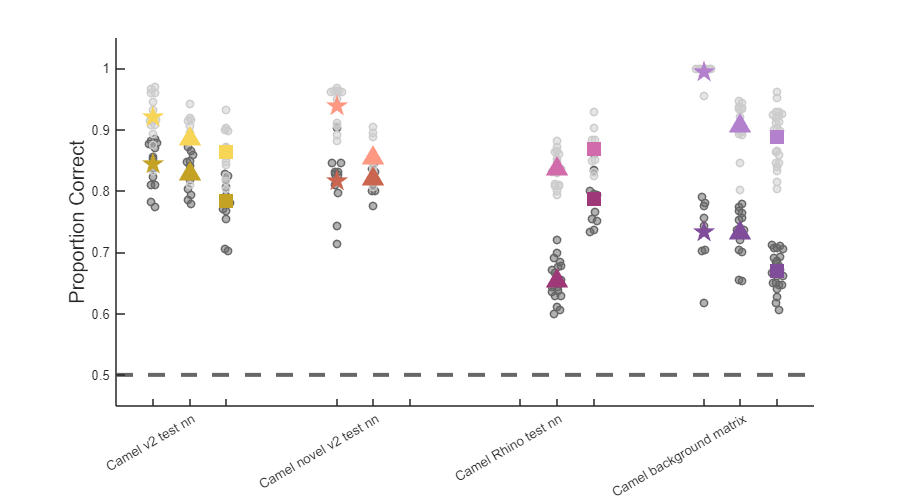

% shrewcolor_exp = [0.38,0.19,0.71;...
%     0.04,0.25,0.73;...
%     0.28,0.52,0.15];
% 
% shrewcolor_ctch = [0.72,0.57,0.98;...
%     0.6,0.78,0.96;...
%     0.62,0.89,0.48];
% 
% shrewmarker_exp = {'_','_','_'};
% 
% shrewmarkcolor_exp = {'k','k','k'};
% 
% shrewmarkcolor_ctch = [0.4,0.4,0.4;...
%     0.4,0.4,0.4;...
%     0.4,0.4,0.4];

shrewcolor_exp = [0.4,0.4,0.4;...
    0.4,0.4,0.4;...
    0.4,0.4,0.4];

shrewcolor_ctch = [0.8,0.8,0.8;...
    0.8,0.8,0.8;...
    0.8,0.8,0.8];

shrewmarker = {'pentagram','^','s'};

plotTest = false;

figure('Renderer', 'painters', 'Position', [10 10 900 500]); hold on;
for task = 1:length(allTasks)
    xvalues = 5*task-4:5*task-2;
    mean_noncatch = cellfun(@nanmean,sessionAcc_nonCatch{task});
    mean_catch = cellfun(@nanmean,sessionAcc_Catch{task});
    ax = plotSpread(sessionAcc_nonCatch{task},'distributionMarkers','o',...
        'distributionColors',shrewcolor_exp,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{task},' '},...
        'categoryLabels',shrewname,...
        'binWidth',0.2);
    
    plotSpread(sessionAcc_Catch{task},'distributionMarkers','o',...
        'distributionColors',shrewcolor_ctch,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{task},' '});
    
    for i = 1:length(xvalues)
        plot(xvalues(i),mean_noncatch(i),'Color',exp_colors(task,:)-0.2,'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:)-0.2,'MarkerSize',12,'linewidth',1.7);
        plot(xvalues(i),mean_catch(i),'Color',exp_colors(task,:),'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:),'MarkerSize',12,'linewidth',1.7);
    end
end


ax{3}.XTick = [1:3,6:8,11:13,16:18];
ax{3}.XTickLabel = {' ',strrep(allTasks{1},'_',' '),' ',' ',strrep(allTasks{2},'_',' '),' ',' ',strrep(allTasks{3},'_',' '),' ',' ',strrep(allTasks{4},'_',' '),' '};
ylim([0.45 1.05])
yticks(0.5:0.1:1)
ylabel('Proportion Correct','fontsize',15)

yline(0.5,'--','LineWidth',3)

figure;hold on;
for taskIdx = 1:3
    taskType = allTasks{taskIdx};
    camel0 = 1;

    allData.Camel_v2_test_nn.TestTarg(allData.Camel_v2_test_nn.TestTarg==398) = 198;

    all_targets = unique(allData.(taskType).T_Expt_ID);
    all_distractors = unique(allData.(taskType).D_Expt_ID);

    test_targets = [unique(allData.(taskType).TestTarg(~isnan(allData.(taskType).TestTarg))); unique(allData.(taskType).NovelTarg(~isnan(allData.(taskType).NovelTarg)))];
    % test_targets = unique(allData.(taskType).T_Expt_ID(isnan(allData.(taskType).ctch)));
    if all(isnan(test_targets))
        holdout = 0.33;
    else
        holdout = [];
    end

    % Extract behavioral performance
    avg_perf = nan(max(all_distractors)+1,max(all_targets)+1);
    for dd = 1:size(avg_perf,1)
        for tt = 1:size(avg_perf,2)
            if strcmp(taskType,'Camel_Rhino_test_nn')
                avg_perf(dd,tt) = mean(allData.(taskType).correct(allData.(taskType).T_Expt_ID==tt-camel0 & allData.(taskType).D_Expt_ID==dd-camel0 & allData.(taskType).ShrewID==3),'omitnan');
            else
                avg_perf(dd,tt) = mean(allData.(taskType).correct(allData.(taskType).T_Expt_ID==tt-camel0 & allData.(taskType).D_Expt_ID==dd-camel0),'omitnan');
            end
        end
    end

    if isempty(holdout)
        test_targets = [unique(allData.(taskType).TestTarg(~isnan(allData.(taskType).TestTarg))); unique(allData.(taskType).NovelTarg(~isnan(allData.(taskType).NovelTarg)))];
        %     test_targets = unique(allData.(taskType).T_Expt_ID(isnan(allData.(taskType).ctch)));
        train_targets = setdiff(all_targets,test_targets);
        test_distractors = [unique(allData.(taskType).TestDist(~isnan(allData.(taskType).TestDist))); unique(allData.(taskType).NovelDist(~isnan(allData.(taskType).NovelDist)))];
        %     test_distractors = unique(allData.(taskType).D_Expt_ID(isnan(allData.(taskType).ctch)));
        train_distractors = setdiff(all_distractors,test_distractors);
        % disp([length(train_targets) length(test_targets); length(train_distractors) length(test_distractors)])
    else
        cv_targ = cvpartition(length(all_targets),'HoldOut',holdout);
        test_targets = all_targets(cv_targ.test);
        train_targets = all_targets(~cv_targ.test);
        cv_dist = cvpartition(length(all_distractors),'HoldOut',holdout);
        test_distractors = all_distractors(cv_dist.test);
        train_distractors = all_distractors(~cv_dist.test);
        % disp([length(train_targets) length(test_targets); length(train_distractors) length(test_distractors)])
    end
    train_perf = avg_perf(train_distractors+camel0,train_targets+camel0);
    test_perf = avg_perf(test_distractors+camel0,test_targets+camel0);

    subplot(2,3,taskIdx);hold on;
    histogram(train_perf,'FaceColor',exp_colors(taskIdx,:))
    xlim([0 1])
    title(taskType)
    xlabel('Training Stim Perf')
    ylabel('Count')

    subplot(2,3,taskIdx+3);hold on;
    histogram(test_perf,'FaceColor',exp_colors(taskIdx,:))
    xlim([0 1])
    xlabel('Test Stim Perf')
    ylabel('Count')
end

## Performance of Novel Unrewarded & Novel Rewarded

incTask = 1:3;
figure; hold on;
for task = 1:length(allTasks)-1
    xvalues = 5*task-4:5*task-2;
    mean_novunrew = cellfun(@nanmean,sessionAcc_NovUnrew{incTask(task)});
    ax = plotSpread(sessionAcc_NovUnrew{incTask(task)},'distributionMarkers','o',...
        'distributionColors',shrewcolor_exp,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{incTask(task)},' '},...
        'categoryLabels',shrewname,...
        'binWidth',0.2);

    for i = 1:length(xvalues)
        plot(xvalues(i),mean_novunrew(i),'Color',exp_colors(incTask(task),:)-0.2,'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:)-0.2,'MarkerSize',12,'linewidth',1.7);
    end
end

ax{3}.XTick = [1:3,6:8,11:13,16:18];
ax{3}.XTickLabel = {' ',strrep(allTasks{1},'_',' '),' ',' ',strrep(allTasks{2},'_',' '),' ',' ',strrep(allTasks{4},'_',' '),' '};
ylim([0.22 1.05])
yticks(0.3:0.1:1)
ylabel('Proportion Correct','fontsize',15)

yline(0.5,'--','LineWidth',3)
title('Novel Unrewarded Avg Perf')

figure; hold on;
for task = 1:length(allTasks)-1
    xvalues = 5*task-4:5*task-2;
    mean_novrew = cellfun(@nanmean,sessionAcc_NovRew{incTask(task)});
    ax = plotSpread(sessionAcc_NovRew{incTask(task)},'distributionMarkers','o',...
        'distributionColors',shrewcolor_exp,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{incTask(task)},' '},...
        'categoryLabels',shrewname,...
        'binWidth',0.2);

    for i = 1:length(xvalues)
        plot(xvalues(i),mean_novrew(i),'Color',exp_colors(incTask(task),:)-0.2,'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:)-0.2,'MarkerSize',12,'linewidth',1.7);
    end
end

ax{3}.XTick = [1:3,6:8,11:13,16:18];
ax{3}.XTickLabel = {' ',strrep(allTasks{1},'_',' '),' ',' ',strrep(allTasks{2},'_',' '),' ',' ',strrep(allTasks{4},'_',' '),' '};
ylim([0.45 1.05])
yticks(0.5:0.1:1)
ylabel('Proportion Correct','fontsize',15)

yline(0.5,'--','LineWidth',3)
title('Novel Rewarded Avg Perf')

## Performance of Novel Rewarded vs Unrewarded

binSize = 20;
figure();
for task = 1:length(allTasks)-1
    subplot(1,length(allTasks)-1,task); hold on;
    for shrew = 1:length(shrewID)
        max_length = max(cellfun(@(x) length(x),sessionPerf_NovRew{task}{shrew}));
        nSess = length(sessionPerf_NovRew{task}{shrew});
        novrew_perfarray = nan(nSess,binSize);
        for ss = 1:nSess
            if length(sessionPerf_NovRew{task}{shrew}{ss})>=binSize
                sessLen = length(sessionPerf_NovRew{task}{shrew}{ss});
                window = sessLen/binSize;
                edges = 1:window:sessLen+window;
                for tt = 1:length(edges)-1
                    if edges(tt+1)>length(sessionPerf_NovRew{task}{shrew}{ss})
                        use_idx = find(1:sessLen>=edges(tt));
                        novrew_perfarray(ss,tt) = mean(sessionPerf_NovRew{task}{shrew}{ss}(use_idx),'omitnan');
                    else
                        use_idx = find(1:sessLen>=edges(tt) & 1:sessLen<edges(tt+1));
                        novrew_perfarray(ss,tt) = mean(sessionPerf_NovRew{task}{shrew}{ss}(use_idx),'omitnan');
                    end
                end
            end
        end
        mean_novrew = mean(novrew_perfarray,1,'omitnan');
        plot(1:length(mean_novrew),mean_novrew,'k')
        
        max_length = max(cellfun(@(x) length(x),sessionPerf_NovUnrew{task}{shrew}));
        nSess = length(sessionPerf_NovUnrew{task}{shrew});
        novunrew_perfarray = nan(nSess,binSize);
        for ss = 1:nSess
            if length(sessionPerf_NovRew{task}{shrew}{ss})>=binSize
                sessLen = length(sessionPerf_NovUnrew{task}{shrew}{ss});
                window = sessLen/binSize;
                edges = 1:window:sessLen+window;
                for tt = 1:length(edges)-1
                    if edges(tt+1)>length(sessionPerf_NovUnrew{task}{shrew}{ss})
                        use_idx = find(1:sessLen>=edges(tt));
                        novunrew_perfarray(ss,tt) = mean(sessionPerf_NovUnrew{task}{shrew}{ss}(use_idx),'omitnan');
                    else
                        use_idx = find(1:sessLen>=edges(tt) & 1:sessLen<edges(tt+1));
                        novunrew_perfarray(ss,tt) = mean(sessionPerf_NovUnrew{task}{shrew}{ss}(use_idx),'omitnan');
                    end
                end
            end
        end
        mean_novunrew = mean(novunrew_perfarray,1,'omitnan');
        plot(1:length(mean_novunrew),mean_novunrew,'k:')
        xlabel('Session Bin')
        ylabel('Avg Performance')
    end
    title(allTasks{task})
    if task==3
        legend('Novel Rew','Novel Unrew','Location','best')
    end
end
figure();
for task = 1:length(allTasks)-1
    subplot(1,length(allTasks)-1,task); hold on;
    for shrew = 1:length(shrewID)
        nSess = length(sessionPerf_NovRew{task}{shrew});
        novrew_perfhalf = nan(nSess,2);
        for ss = 1:nSess
            max_length = length(sessionPerf_NovRew{task}{shrew}{ss});
            novrew_perfhalf(ss,1) = mean(sessionPerf_NovRew{task}{shrew}{ss}(1:round(max_length/2)),'omitnan');
            novrew_perfhalf(ss,2) = mean(sessionPerf_NovRew{task}{shrew}{ss}(round(max_length/2)+1:end),'omitnan');
        end
        mean_novrew = mean(novrew_perfhalf,1,'omitnan');
        plot(1:2,mean_novrew,'g')
        scatter(1:2,novrew_perfhalf,'g')
        
        nSess = length(sessionPerf_NovUnrew{task}{shrew});
        novunrew_perfhalf = nan(nSess,2);
        for ss = 1:nSess
            max_length = length(sessionPerf_NovUnrew{task}{shrew}{ss});
            novunrew_perfhalf(ss,1) = mean(sessionPerf_NovUnrew{task}{shrew}{ss}(1:round(max_length/2)),'omitnan');
            novunrew_perfhalf(ss,2) = mean(sessionPerf_NovUnrew{task}{shrew}{ss}(round(max_length/2)+1:end),'omitnan');
        end
        mean_novunrew = mean(novunrew_perfhalf,1,'omitnan');
        plot(1:2,mean_novunrew,'r')
        scatter(1:2,novunrew_perfhalf,'r')
    end
    xticks([1,2])
    xticklabels({'1st half session','2nd half session'})
    ylabel('Avg Performance')
    title(allTasks{task})
    if task==3
        legend('Novel Rew','Novel Unrew','Location','best')
    end
end
novrew_perf = {};
novunrew_perf = {};
figure();
for task = 1:length(allTasks)-1
    subplot(1,length(allTasks)-1,task); hold on;
    for shrew = 1:length(shrewID)
        nSess = length(sessionPerf_NovRew{task}{shrew});
        novrew_perf{shrew} = nan(nSess,1);
        for ss = 1:nSess
            novrew_perf{shrew}(ss) = mean(sessionPerf_NovRew{task}{shrew}{ss},'omitnan');
        end
        % mean_novrew = mean(novrew_perf,1,'omitnan');
        plot(1:length(novrew_perf{shrew}),novrew_perf{shrew},'Color',exp_colors(shrew,:)-0.2,'LineWidth',1.5)
        % scatter(1:2,novrew_perf,'g')
        
        nSess = length(sessionPerf_NovUnrew{task}{shrew});
        novunrew_perf{shrew} = nan(nSess,1);
        for ss = 1:nSess
            max_length = length(sessionPerf_NovUnrew{task}{shrew}{ss});
            novunrew_perf{shrew}(ss) = mean(sessionPerf_NovUnrew{task}{shrew}{ss},'omitnan');
        end
        % mean_novunrew = mean(novunrew_perfhalf,1,'omitnan');
        plot(1:length(novunrew_perf{shrew}),novunrew_perf{shrew},':','Color',exp_colors(shrew,:)-0.2,'LineWidth',1.5)
        % scatter(1:2,novunrew_perfhalf,'r')
    end
    xlabel('Sessions')
    ylabel('Avg Performance')
    title(allTasks{task})
    if task==3
        legend('Novel Rew','Novel Unrew','Location','best')
    end
end

## Summary of within- and between-shrew correlations

r = {};
ci = {};
r_split = {};
ci_split = {};

figure();hold on;

for task = 1:length(allTasks)
    nShrews = length(unique(allData.(allTasks{task}).ShrewID));
    uniqueShrew = unique(allData.(allTasks{task}).ShrewID);
    idx_comb = [1,2;1,3;2,3];
    cmap = [255,113,183;218,85,2;255,176,0] / 255;
    for ts = uniqueShrew'
        for it = 1:1000
            [perf1,perf2,xFit,yFit] = corr_fun(targPerf_split1{task,ts}(:,it),targPerf_split2{task,ts}(:,it));
            if ~isempty(perf1) && ~isempty(perf2)
                r_it{task}(ts,it) = corr(perf1,perf2,'rows','complete','Type','Spearman');
            else
                r_it{task}(ts,it) = nan;
            end
        end
        r_split{task}(ts) = mean(r_it{task}(ts,:),'omitnan');
        ci_split{task}(ts,:) = [r_split{task}(ts) - 2*std(r_it{task}(ts,:),'omitnan') r_split{task}(ts) + 2*std(r_it{task}(ts,:),'omitnan')];
        
        plot(2*task-1+ts*0.15,r_split{task}(ts),shrewmarker{ts},'LineWidth',2,'Color',exp_colors(task,:),'MarkerFaceColor',exp_colors(task,:),'MarkerSize',12)
        errorbar(2*task-1+ts*0.15,r_split{task}(ts),ci_split{task}(ts,1)-r_split{task}(ts),r_split{task}(ts)-ci_split{task}(ts,2),'LineWidth',2,'Color',exp_colors(task,:))
    end
    if nShrews < 3
        cmap = cmap(sum(idx_comb,2)==sum(uniqueShrew),:);
        idx_comb = uniqueShrew';
        nShrews = 1;
    end
    for ts = 1:nShrews
        [perf1,perf2,xFit,yFit] = corr_fun(targPerf{task,idx_comb(ts,1)}(:),targPerf{task,idx_comb(ts,2)}(:));
        r{task}(ts) = corr(perf1,perf2,'rows','complete','Type','Spearman');
        mycorr = @(x1,x2) corr(x1,x2,'rows','complete','Type','Spearman');
        ci{task}(ts,:) = bootci(1000,{mycorr,perf1,perf2});

        plot(2*task-0.5+ts*0.15,r{task}(ts)+0.015,shrewmarker{idx_comb(ts,1)},'LineWidth',2,'Color',exp_colors(task,:),'MarkerFaceColor',exp_colors(task,:),'MarkerSize',12)
        plot(2*task-0.5+ts*0.15,r{task}(ts)-0.015,shrewmarker{idx_comb(ts,2)},'LineWidth',2,'Color',exp_colors(task,:),'MarkerFaceColor',exp_colors(task,:),'MarkerSize',12)
        errorbar(2*task-0.5+ts*0.15,r{task}(1),ci{task}(ts,1)-r{task}(1),r{task}(1)-ci{task}(ts,2),'LineWidth',2,'Color',exp_colors(task,:))
    end
    
end
yline(0,':','LineWidth',1.5)
xlim([0.8 8])
ylim([-0.47 1.05])



## Avg performance for novel stim trial types

sessType = 1;

data = cell(2,2);
for ts = 1:3
    data{1,1} = [data{1,1} sessionAcc_Familiar{sessType}{ts}];
    data{1,2} = [data{1,2} sessionAcc_NovTarg{sessType}{ts}];
    data{2,1} = [data{2,1} sessionAcc_NovDist{sessType}{ts}];
    data{2,2} = [data{2,2} sessionAcc_NovBoth{sessType}{ts}];
end

perf = cellfun(@(x) mean(x,'omitnan'), data);
x = {'Fam. Targ.','Nov. Targ.'};
y = {'Fam. Dist.','Nov. Dist.'};

figure('Renderer', 'painters', 'Position', [10 10 1300 300]);
subplot(1,3,1)
heatmap(x,y,perf)
caxis([0.5 1])
title(allTasks{sessType})

sessType = 2;

data = cell(2,2);
for ts = 1:3
    data{1,1} = [data{1,1} sessionAcc_Familiar{sessType}{ts}];
    data{1,2} = [data{1,2} sessionAcc_NovTarg{sessType}{ts}];
    data{2,1} = [data{2,1} sessionAcc_NovDist{sessType}{ts}];
    data{2,2} = [data{2,2} sessionAcc_NovBoth{sessType}{ts}];
end

perf = cellfun(@(x) mean(x,'omitnan'), data);
x = {'Fam. Targ.','Nov. Targ.'};
y = {'Fam. Dist.','Nov. Dist.'};

subplot(1,3,2)
heatmap(x,y,perf)
caxis([0.5 1])
title(allTasks{sessType})

sessType = 3;

data = cell(2,2);
for ts = 1:3
    data{1,1} = [data{1,1} sessionAcc_Familiar{sessType}{ts}];
    data{1,2} = [data{1,2} sessionAcc_NovTarg{sessType}{ts}];
    data{2,1} = [data{2,1} sessionAcc_NovDist{sessType}{ts}];
    data{2,2} = [data{2,2} sessionAcc_NovBoth{sessType}{ts}];
end

perf = cellfun(@(x) mean(x,'omitnan'), data);
x = {'Fam. Targ.','Nov. Targ.'};
y = {'Fam. Dist.','Nov. Dist.'};

subplot(1,3,3)
heatmap(x,y,perf)
colormap(parula)
caxis([0.5 1])
title(allTasks{sessType})

## Performance across transformations/image statistics

task = 1;

if task == 1
    dist_data = load(['C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/',allTasks{task},'/wrench_matched.mat']);
    dist_data = dist_data.tab;
    
    scale_bin_tt = 0.6:0.2:1.6;
    scale_bin_dd = 0.6:0.2:1.4;
    
    trans_bin_tt = -1:0.4:0.6;
    trans_bin_dd = -1:0.4:0.6;
    
    transXY_bin_tt = 0.2:0.2:1;
    transXY_bin_dd = 0:0.2:1;
    
    rot_bin_tt = -180:90:90;
    rot_bin_dd = -180:90:90;
    
    rot_Q_tt = 90:15:90;
    rot_Q_dd = 30:30:90;
    
%     lum_tt = 122:126;
%     lum_dd = 125:0.5:126.5;

    lum_tt = 70:5:85;
    lum_dd = 60:5:75;
    
    pix_tt = -2:0.5:2;
    pix_dd = -2:0.25:-0.75;
    
elseif task == 3
    dist_data = load(['C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/',allTasks{task},'/rhino_matched.mat']);
    dist_data = dist_data.tab;
    
    scale_bin_tt = 0.6:0.2:1.6;
    scale_bin_dd = 0.6:0.2:1.6;
    
    trans_bin_tt = -1:0.4:0.6;
    trans_bin_dd = -1:0.4:0.6;
    
    transXY_bin_tt = 0:0.2:1;
    transXY_bin_dd = 0:0.2:1.2;
    
    rot_bin_tt = -180:90:90;
    rot_bin_dd = -180:90:90;
    
    rot_Q_tt = 90:15:165;
    rot_Q_dd = 75:15:165;

    lum_tt = 75:2.5:85;
    lum_dd = 65:2:73;
%     lum_tt = 122:126;
%     lum_dd = 119:125;
    
    pix_tt = -1.5:0.5:1.5;
    pix_dd = -2:5;
        
end

targ_data = load(['C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/',allTasks{task},'/camel_matched.mat']);
targ_data = targ_data.tab;

use_data = allData.(allTasks{task});

shrewID = unique(use_data.ShrewID);
targID = unique(use_data.T_Expt_ID);targID = targID(targID>0 & targID<=100);
distID = unique(use_data.D_Expt_ID);distID = distID(distID>0 & distID<=100);

targ_stim = {};
for tt = 1:size(targ_data,1)
    targ_stim{tt} = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/target_%d.png',allTasks{task},tt)));
end
targ_0 = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/target_%d.png',allTasks{task},0)));

dist_stim = {};
for dd = 1:size(dist_data,1)
    dist_stim{dd} = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/distractor_%d.png',allTasks{task},dd)));
end
dist_0 = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/distractor_%d.png',allTasks{task},0)));

all_trans_tt = sqrt(targ_data.TY.^2 + targ_data.TZ.^2);
all_trans_dd = sqrt(dist_data.TY.^2 + dist_data.TZ.^2);

lum_targ = cellfun(@(x) mean(x(x~=127),'all'), targ_stim);
lum_dist = cellfun(@(x) mean(x(x~=127),'all'), dist_stim);

pix_targ = cellfun(@(x) mean(targ_0-x,'all'), targ_stim);
pix_dist = cellfun(@(x) mean(targ_0-x,'all'), dist_stim);

scale_mat_perf = cell(length(scale_bin_dd),length(scale_bin_tt));
scale_vec_perf = cell(length(scale_bin_tt),1);
scale_vec = cell(length(scale_bin_tt),1);
transX_mat_perf = cell(length(trans_bin_dd),length(trans_bin_tt));
transX_vec_perf = cell(length(trans_bin_tt),1);
transX_vec = cell(length(trans_bin_tt),1);
transY_mat_perf = cell(length(trans_bin_dd),length(trans_bin_tt));
transY_vec_perf = cell(length(trans_bin_tt),1);
transY_vec = cell(length(trans_bin_tt),1);
transXY_mat_perf = cell(length(transXY_bin_dd),length(transXY_bin_tt));
transXY_vec_perf = cell(length(transXY_bin_tt),1);
transXY_vec = cell(length(transXY_bin_tt),1);
rotXY_mat_perf = cell(length(rot_bin_dd),length(rot_bin_tt));
rotXY_vec_perf = cell(length(rot_bin_tt),1);
rotXY_vec = cell(length(rot_bin_tt),1);
rotXZ_mat_perf = cell(length(rot_bin_dd),length(rot_bin_tt));
rotXZ_vec_perf = cell(length(rot_bin_tt),1);
rotXZ_vec = cell(length(rot_bin_tt),1);
rotYZ_mat_perf = cell(length(rot_bin_dd),length(rot_bin_tt));
rotYZ_vec_perf = cell(length(rot_bin_tt),1);
rotYZ_vec = cell(length(rot_bin_tt),1);
lum_mat_perf = cell(length(lum_dd),length(lum_tt));
lum_vec_perf = cell(length(lum_tt),1);
lum_vec = cell(length(lum_tt),1);
pix_mat_perf = cell(length(pix_dd),length(pix_tt));
pix_vec_perf = cell(length(pix_tt),1);
pix_vec = cell(length(pix_tt),1);
for tt = 1:length(targID)
    for dd = 1:length(distID)
        if targID(tt)<=100
            targID_new = targID;
        else
            targID_new = targID-floor(targID(tt)/100)*100;
        end
        if distID(dd)<=100
            distID_new = distID;
        else
            distID_new = distID-floor(distID(dd)/100)*100;
        end
        
        perf_cat = mean(use_data.correct(use_data.T_Expt_ID==targID(tt) & use_data.D_Expt_ID==distID(dd) & use_data.ctch==0),'omitnan');
        
        % Scale All
        temp_tt = find((targ_data(targID_new(tt),:).Scale - scale_bin_tt)>0);
        temp_dd = find((dist_data(distID_new(dd),:).Scale - scale_bin_dd)>0);
        idx_scale_tt = temp_tt(end); idx_scale_dd = temp_dd(end);
        
        scale_mat_perf{idx_scale_dd,idx_scale_tt} = [scale_mat_perf{idx_scale_dd,idx_scale_tt} perf_cat];
        
        % X Translation
        temp_tt = find((targ_data(targID_new(tt),:).TY - trans_bin_tt)>0);
        temp_dd = find((dist_data(distID_new(dd),:).TY - trans_bin_dd)>0);
        idx_transX_tt = temp_tt(end); idx_transX_dd = temp_dd(end);

        transX_mat_perf{idx_transX_dd,idx_transX_tt} = [transX_mat_perf{idx_transX_dd,idx_transX_tt} perf_cat];
        
        % Y Translation
        temp_tt = find((targ_data(targID_new(tt),:).TZ - trans_bin_tt)>0);
        temp_dd = find((dist_data(distID_new(dd),:).TZ - trans_bin_dd)>0);
        idx_transY_tt = temp_tt(end); idx_transY_dd = temp_dd(end);

        transY_mat_perf{idx_transY_dd,idx_transY_tt} = [transY_mat_perf{idx_transY_dd,idx_transY_tt} perf_cat];
        
        % XY Translation
        temp_tt = find((all_trans_tt(targID_new(tt)) - transXY_bin_tt)>0);
        temp_dd = find((all_trans_dd(distID_new(dd)) - transXY_bin_dd)>0);
        idx_transXY_tt = temp_tt(end); idx_transXY_dd = temp_dd(end);

        transXY_mat_perf{idx_transXY_dd,idx_transXY_tt} = [transXY_mat_perf{idx_transXY_dd,idx_transXY_tt} perf_cat];
        
        % XY Rotation
        temp_tt = find((targ_data(targID_new(tt),:).RXY - rot_bin_tt)>0);
        temp_dd = find((dist_data(distID_new(dd),:).RXY - rot_bin_tt)>0);
        idx_rotXY_tt = temp_tt(end); idx_rotXY_dd = temp_dd(end);

        rotXY_mat_perf{idx_rotXY_dd,idx_rotXY_tt} = [rotXY_mat_perf{idx_rotXY_dd,idx_rotXY_tt} perf_cat];
        
        % XZ Rotation
        temp_tt = find((targ_data(targID_new(tt),:).RXZ - rot_bin_tt)>0);
        temp_dd = find((dist_data(distID_new(dd),:).RXZ - rot_bin_tt)>0);
        idx_rotXZ_tt = temp_tt(end); idx_rotXZ_dd = temp_dd(end);

        rotXZ_mat_perf{idx_rotXZ_dd,idx_rotXZ_tt} = [rotXZ_mat_perf{idx_rotXZ_dd,idx_rotXZ_tt} perf_cat];
        
        % YZ Rotation
        temp_tt = find((targ_data(targID_new(tt),:).RYZ - rot_bin_tt)>0);
        temp_dd = find((dist_data(distID_new(dd),:).RYZ - rot_bin_tt)>0);
        idx_rotYZ_tt = temp_tt(end); idx_rotYZ_dd = temp_dd(end);

        rotYZ_mat_perf{idx_rotYZ_dd,idx_rotYZ_tt} = [rotYZ_mat_perf{idx_rotYZ_dd,idx_rotYZ_tt} perf_cat];
        
        % Luminance
        temp_tt = find((lum_targ(targID_new(tt)) - lum_tt)>0);
        temp_dd = find((lum_dist(distID_new(dd)) - lum_dd)>0);
        idx_lum_tt = temp_tt(end); idx_lum_dd = temp_dd(end);

        lum_mat_perf{idx_lum_dd,idx_lum_tt} = [lum_mat_perf{idx_lum_dd,idx_lum_tt} perf_cat];
        
        % Pixel Difference
        temp_tt = find((pix_targ(targID_new(tt)) - pix_tt)>0);
        temp_dd = find((pix_dist(distID_new(dd)) - pix_dd)>0);
        idx_pix_tt = temp_tt(end); idx_pix_dd = temp_dd(end);

        pix_mat_perf{idx_pix_dd,idx_pix_tt} = [pix_mat_perf{idx_pix_dd,idx_pix_tt} perf_cat];

    end
    
    perf_cat = mean(use_data.correct(use_data.T_Expt_ID==targID(tt) & use_data.ctch==0),'omitnan');
    Y(tt) = perf_cat;
    
    % Scale Targ
    scale_vec_perf{idx_scale_tt} = [scale_vec_perf{idx_scale_tt} perf_cat];
    scale_vec{idx_scale_tt} = [scale_vec{idx_scale_tt} targ_data(targID_new(tt),:).Scale];
    
    % Trans X Targ
    transX_vec_perf{idx_transX_tt} = [transX_vec_perf{idx_transX_tt} perf_cat];
    transX_vec{idx_transX_tt} = [transX_vec{idx_transX_tt} targ_data(targID_new(tt),:).TY];
    
    % Trans Y Targ
    transY_vec_perf{idx_transY_tt} = [transY_vec_perf{idx_transY_tt} perf_cat];
    transY_vec{idx_transY_tt} = [transY_vec{idx_transY_tt} targ_data(targID_new(tt),:).TZ];
    
    % Trans XY Targ
    transXY_vec_perf{idx_transXY_tt} = [transXY_vec_perf{idx_transXY_tt} perf_cat];
    transXY_vec{idx_transXY_tt} = [transXY_vec{idx_transXY_tt} all_trans_tt(targID_new(tt))];
    
    % Rot XY Targ
    rotXY_vec_perf{idx_rotXY_tt} = [rotXY_vec_perf{idx_rotXY_tt} perf_cat];
    rotXY_vec{idx_rotXY_tt} = [rotXY_vec{idx_rotXY_tt} targ_data(targID_new(tt),:).RXY];
    
    % Rot XZ Targ
    rotXZ_vec_perf{idx_rotXZ_tt} = [rotXZ_vec_perf{idx_rotXZ_tt} perf_cat];
    rotXZ_vec{idx_rotXZ_tt} = [rotXZ_vec{idx_rotXZ_tt} targ_data(targID_new(tt),:).RXZ];
    
    % Rot YZ Targ
    rotYZ_vec_perf{idx_rotYZ_tt} = [rotYZ_vec_perf{idx_rotYZ_tt} perf_cat];
    rotYZ_vec{idx_rotYZ_tt} = [rotYZ_vec{idx_rotYZ_tt} targ_data(targID_new(tt),:).RYZ];
    
    % Luminance Targ
    lum_vec_perf{idx_lum_tt} = [lum_vec_perf{idx_lum_tt} perf_cat];
    lum_vec{idx_lum_tt} = [lum_vec{idx_lum_tt} lum_targ(targID(tt))];
    
    % Pixel Targ
    pix_vec_perf{idx_pix_tt} = [pix_vec_perf{idx_pix_tt} perf_cat];
    pix_vec{idx_pix_tt} = [pix_vec{idx_pix_tt} pix_targ(targID(tt))];
    
    X(tt,:) = [targ_data(targID_new(tt),:).Scale, targ_data(targID_new(tt),:).TY, targ_data(targID_new(tt),:).TZ, all_trans_tt(targID_new(tt)),...
        targ_data(targID_new(tt),:).RXY, targ_data(targID_new(tt),:).RXZ, targ_data(targID_new(tt),:).RYZ, lum_targ(targID(tt)), pix_targ(targID(tt))];
    
end

bin_dd = {scale_bin_dd,trans_bin_dd,trans_bin_dd,transXY_bin_dd,rot_bin_dd,rot_bin_dd,rot_bin_dd,lum_dd,pix_dd};
bin_tt = {scale_bin_tt,trans_bin_tt,trans_bin_tt,transXY_bin_tt,rot_bin_tt,rot_bin_tt,rot_bin_tt,lum_tt,pix_tt};
mat_perf = {scale_mat_perf,transX_mat_perf,transY_mat_perf,transXY_mat_perf,rotXY_mat_perf,rotXZ_mat_perf,rotYZ_mat_perf,lum_mat_perf,pix_mat_perf};
vec_perf = {scale_vec_perf,transX_vec_perf,transY_vec_perf,transXY_vec_perf,rotXY_vec_perf,rotXZ_vec_perf,rotYZ_vec_perf,lum_vec_perf,pix_vec_perf};
vecs = {scale_vec,transX_vec,transY_vec,transXY_vec,rotXY_vec,rotXZ_vec,rotYZ_vec,lum_vec,pix_vec};
labels = {'Scale','X Translation','Y Translation','Dist. from Center','XY Rotation','XZ Rotation','YZ Rotation','Luminance','Pixel Difference'};

for idx = 1:length(mat_perf)
    mat_mean_perf{idx} = cell2mat(cellfun(@(x) mean(x,'all','omitnan'),mat_perf{idx},'UniformOutput',false));
    vec_targ_perf{idx} = cell2mat(cellfun(@(x) mean(x,'all','omitnan'),vec_perf{idx},'UniformOutput',false));
    vec_targ_std{idx} = cell2mat(cellfun(@(x) std(x,[],'all','omitnan'),vec_perf{idx},'UniformOutput',false));
end

figure('Renderer', 'painters', 'Position', [10 10 1600 600]);
tiledlayout('flow','TileSpacing','compact')
for idx = 1:length(mat_perf)
    nexttile;
    heatmap(bin_tt{idx},bin_dd{idx},mat_mean_perf{idx},'CellLabelColor','none')
    colormap(parula)
    caxis([0.5 1])
    title(labels{idx})
end

% figure('Renderer', 'painters', 'Position', [10 10 1600 600]);
% tiledlayout('flow','TileSpacing','compact')
% for idx = 1:length(vec_targ_perf)
%     nexttile;
%     shadedErrorBar(bin_tt{idx},vec_targ_perf{idx},vec_targ_std{idx})
%     ylim([0.5 1])
% end

figure('Renderer', 'painters', 'Position', [10 10 1800 600]);
tiledlayout('flow','TileSpacing','compact');
for idx = 1:length(vecs)
    nexttile;
    perf_all = [vec_perf{idx}{:}];
    vecs_all = [vecs{idx}{:}];
    nanval = ~isnan(perf_all); 
    perf_all = perf_all(nanval); vecs_all = vecs_all(nanval);
    
    plot(vecs_all,perf_all,'o')
    hold on;
    
    [fits2,gof2] = fit(vecs_all',perf_all','poly2');
    [fits1,gof1] = fit(vecs_all',perf_all','poly1');
    if gof1.adjrsquare>gof2.adjrsquare
        fits = fits1;
    else
        fits = fits2;
    end
    x1 = linspace(min(vecs_all),max(vecs_all));
    y1 = feval(fits,x1);
    ci = predint(fits,x1);
    err = [y1 - ci(:,1),ci(:,2)-y1];
    shadedErrorBar(x1,y1,err')
    plot(x1,y1,'k')
    
%     [p,S] = polyfit(vecs_all,perf_all,2);
%     x1 = linspace(min(vecs_all)-0.1,max(vecs_all)+0.1);
%     [y1,delta] = polyval(p,x1,S);
%     shadedErrorBar(x1,y1,delta)
%     plot(x1,y1,'k')
    ylim([0.45 1.07])
    xlabel(labels{idx})
    ylabel('Performance')
    box off
end
mdl = fitlm(X,Y,'VarNames',[labels {'Resp'}]);
figure;
bar(mdl.Coefficients.Estimate(2:end,:))
xticklabels(labels)
mdl = stepwiselm(X,Y,'purequadratic','VarNames',[labels {'Resp'}]);
figure;
bar(1:length(mdl.Coefficients.Estimate(2:end)),mdl.Coefficients.Estimate(2:end))
xticks(1:length(mdl.Coefficients.Estimate(2:end)))
xticklabels(mdl.CoefficientNames(2:end))
include = find(abs(mdl.Coefficients.Estimate(2:end))>0.1);
figure;
bar(1:length(include),mdl.Coefficients.Estimate(include+1))
xticks(1:length(include))
xticklabels(mdl.CoefficientNames(include+1))


task = 3;

if task == 1
    dist_data = load(['C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/',allTasks{task},'/wrench_matched.mat']);
    dist_data = dist_data.tab;
    
    scale_bin_tt = 0.6:0.2:1.6;
    scale_bin_dd = 0.6:0.2:1.4;
    
    transXY_bin_tt = 0.2:0.2:1;
    transXY_bin_dd = 0:0.2:1;

    lum_tt = 70:5:85;
    lum_dd = 60:5:75;
    
    pix_tt = -2:0.5:2;
    pix_dd = -2:0.25:-0.75;
    
elseif task == 3
    dist_data = load(['C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/',allTasks{task},'/rhino_matched.mat']);
    dist_data = dist_data.tab;
    
    scale_bin_tt = 0.6:0.2:1.6;
    scale_bin_dd = 0.6:0.2:1.6;
    
    transXY_bin_tt = 0:0.2:1;
    transXY_bin_dd = 0:0.2:1.2;

    lum_tt = 75:2.5:85;
    lum_dd = 65:2:73;
    
    pix_tt = -1.5:0.5:1.5;
    pix_dd = -2:5;
        
end

use_data = allData.(allTasks{task});

shrewID = unique(use_data.ShrewID);
targID = unique(use_data.T_Expt_ID);targID = targID(targID>0 & targID<=100);
distID = unique(use_data.D_Expt_ID);distID = distID(distID>0 & distID<=100);

targ_stim = {};
for tt = 1:max(targID)
    targ_stim{tt} = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/target_%d.png',allTasks{task},tt)));
end
targ_0 = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/target_%d.png',allTasks{task},0)));

dist_stim = {};
for dd = 1:max(distID)
    dist_stim{dd} = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/distractor_%d.png',allTasks{task},dd)));
end
dist_0 = double(imread(sprintf('C:/Users/eemeyer/Documents/GitHub/TreeShrewObjRec/rawStims/%s/original/distractor_%d.png',allTasks{task},0)));

all_trans_tt = sqrt(targ_data.TY.^2 + targ_data.TZ.^2);
all_trans_dd = sqrt(dist_data.TY.^2 + dist_data.TZ.^2);

% lum_targ = cellfun(@(x) mean(x,'all'), targ_stim);
% lum_dist = cellfun(@(x) mean(x,'all'), dist_stim);

lum_targ = cellfun(@(x) mean(x(x~=127),'all'), targ_stim);
lum_dist = cellfun(@(x) mean(x(x~=127),'all'), dist_stim);

pix_targ = cellfun(@(x) mean(targ_0-x,'all'), targ_stim);
pix_dist = cellfun(@(x) mean(targ_0-x,'all'), dist_stim);

scale_mat_perf = cell(length(scale_bin_dd),length(scale_bin_tt));
scale_vec_perf = cell(length(scale_bin_tt),1);
scale_vec = cell(length(scale_bin_tt),1);
transXY_mat_perf = cell(length(transXY_bin_dd),length(transXY_bin_tt));
transXY_vec_perf = cell(length(transXY_bin_tt),1);
transXY_vec = cell(length(transXY_bin_tt),1);
lum_mat_perf = cell(length(lum_dd),length(lum_tt));
lum_vec_perf = cell(length(lum_tt),1);
lum_vec = cell(length(lum_tt),1);
pix_mat_perf = cell(length(pix_dd),length(pix_tt));
pix_vec_perf = cell(length(pix_tt),1);
pix_vec = cell(length(pix_tt),1);
for tt = 1:length(targID)
    for dd = 1:length(distID)
        if targID(tt)<=100
            targID_new = targID;
        else
            targID_new = targID-floor(targID(tt)/100)*100;
        end
        if distID(dd)<=100
            distID_new = distID;
        else
            distID_new = distID-floor(distID(dd)/100)*100;
        end
        
        perf_cat = mean(use_data.correct(use_data.T_Expt_ID==targID(tt) & use_data.D_Expt_ID==distID(dd) & use_data.ctch==0),'omitnan');
        
        % Scale All
        temp_tt = find((targ_data(targID_new(tt),:).Scale - scale_bin_tt)>0);
        temp_dd = find((dist_data(distID_new(dd),:).Scale - scale_bin_dd)>0);
        idx_scale_tt = temp_tt(end); idx_scale_dd = temp_dd(end);
        
        scale_mat_perf{idx_scale_dd,idx_scale_tt} = [scale_mat_perf{idx_scale_dd,idx_scale_tt} perf_cat];
        
        % XY Translation
        temp_tt = find((all_trans_tt(targID_new(tt)) - transXY_bin_tt)>0);
        temp_dd = find((all_trans_dd(distID_new(dd)) - transXY_bin_dd)>0);
        idx_transXY_tt = temp_tt(end); idx_transXY_dd = temp_dd(end);

        transXY_mat_perf{idx_transXY_dd,idx_transXY_tt} = [transXY_mat_perf{idx_transXY_dd,idx_transXY_tt} perf_cat];
        
        % Luminance
        temp_tt = find((lum_targ(targID(tt)) - lum_tt)>0);
        temp_dd = find((lum_dist(distID(dd)) - lum_dd)>0);
        idx_lum_tt = temp_tt(end); idx_lum_dd = temp_dd(end);

        lum_mat_perf{idx_lum_dd,idx_lum_tt} = [lum_mat_perf{idx_lum_dd,idx_lum_tt} perf_cat];
        
        % Pixel Difference
        temp_tt = find((pix_targ(targID(tt)) - pix_tt)>0);
        temp_dd = find((pix_dist(distID(dd)) - pix_dd)>0);
        idx_pix_tt = temp_tt(end); idx_pix_dd = temp_dd(end);

        pix_mat_perf{idx_pix_dd,idx_pix_tt} = [pix_mat_perf{idx_pix_dd,idx_pix_tt} perf_cat];

    end
    
    perf_cat = mean(use_data.correct(use_data.T_Expt_ID==targID(tt) & use_data.ctch==0),'omitnan');
    
    % Scale Targ
    scale_vec_perf{idx_scale_tt} = [scale_vec_perf{idx_scale_tt} perf_cat];
    scale_vec{idx_scale_tt} = [scale_vec{idx_scale_tt} targ_data(targID_new(tt),:).Scale];
    
    % Trans XY Targ
    transXY_vec_perf{idx_transXY_tt} = [transXY_vec_perf{idx_transXY_tt} perf_cat];
    transXY_vec{idx_transXY_tt} = [transXY_vec{idx_transXY_tt} all_trans_tt(targID_new(tt))];
    
    % Luminance Targ
    lum_vec_perf{idx_lum_tt} = [lum_vec_perf{idx_lum_tt} perf_cat];
    lum_vec{idx_lum_tt} = [lum_vec{idx_lum_tt} lum_targ(targID(tt))];
    
    % Pixel Targ
    pix_vec_perf{idx_pix_tt} = [pix_vec_perf{idx_pix_tt} perf_cat];
    pix_vec{idx_pix_tt} = [pix_vec{idx_pix_tt} pix_targ(targID(tt))];
    
end

bin_dd = {scale_bin_dd,transXY_bin_dd,lum_dd,pix_dd};
bin_tt = {scale_bin_tt,transXY_bin_tt,lum_tt,pix_tt};
mat_perf = {scale_mat_perf,transXY_mat_perf,lum_mat_perf,pix_mat_perf};
vec_perf = {scale_vec_perf,transXY_vec_perf,lum_vec_perf,pix_vec_perf};
vecs = {scale_vec,transXY_vec,lum_vec,pix_vec};
labels = {'Scale','Dist. from Center','Luminance','Pixel Difference'};

mat_mean_perf = {};
vec_targ_perf = {};
vec_targ_std = {};
for idx = 1:length(mat_perf)
    mat_mean_perf{idx} = cell2mat(cellfun(@(x) mean(x,'all','omitnan'),mat_perf{idx},'UniformOutput',false));
    vec_targ_perf{idx} = cell2mat(cellfun(@(x) mean(x,'all','omitnan'),vec_perf{idx},'UniformOutput',false));
    vec_targ_std{idx} = cell2mat(cellfun(@(x) std(x,[],'all','omitnan'),vec_perf{idx},'UniformOutput',false));
end

% figure('Renderer', 'painters', 'Position', [10 10 1800 370]);
% tiledlayout(1,4,'TileSpacing','compact')
% for idx = 1:length(mat_perf)
%     nexttile;
%     if task==3 && (idx==1 || idx==2)
%         heatmap(bin_tt{idx}(2:end),bin_dd{idx}(2:end),mat_mean_perf{idx}(2:end,2:end),'CellLabelColor','none')
%     else
%         heatmap(bin_tt{idx},bin_dd{idx},mat_mean_perf{idx},'CellLabelColor','none')
%     end
%     colormap(parula)
%     caxis([0.5 1])
%     title(labels{idx})
% end
figure('Renderer', 'painters', 'Position', [10 10 1600 400]);
tiledlayout(1,4,'TileSpacing','compact')
for idx = 1:length(mat_perf)
    nexttile;
    heatmap(bin_tt{idx},bin_dd{idx},mat_mean_perf{idx},'CellLabelColor','none')
    colormap(parula)
    caxis([0.5 1])
    title(labels{idx})
end
% 
% figure('Renderer', 'painters', 'Position', [10 10 800 600]);
% tiledlayout('flow','TileSpacing','compact')
% for idx = 1:length(vec_targ_perf)
%     nexttile;
%     shadedErrorBar(bin_tt{idx},vec_targ_perf{idx},vec_targ_std{idx})
%     ylim([0.5 1])
%     xlabel(labels{idx})
%     ylabel('Performance')
% end

% figure('Renderer', 'painters', 'Position', [10 10 1800 400]);
% tiledlayout(1,4,'TileSpacing','compact');
% for idx = 1:length(vecs)
%     nexttile;
%     perf_all = [vec_perf{idx}{:}];
%     vecs_all = [vecs{idx}{:}];
%     nanval = ~isnan(perf_all); 
%     perf_all = perf_all(nanval); vecs_all = vecs_all(nanval);
%     
%     plot(vecs_all,perf_all,'o')
%     hold on;
%     [p,S] = polyfit(vecs_all,perf_all,2);
%     x1 = linspace(min(vecs_all)-0.1,max(vecs_all)+0.1);
%     [y1,delta] = polyval(p,x1,S);
%     shadedErrorBar(x1,y1,delta)
%     plot(x1,y1,'k')
%     ylim([0.45 1.07])
%     xlabel(labels{idx})
%     ylabel('Performance')
%     box off
% end


figure('Renderer', 'painters', 'Position', [10 10 1800 400]);
tiledlayout(1,4,'TileSpacing','compact');
for idx = 1:length(vecs)
    nexttile;
    perf_all = [vec_perf{idx}{:}];
    vecs_all = [vecs{idx}{:}];
    nanval = ~isnan(perf_all); 
    perf_all = perf_all(nanval); vecs_all = vecs_all(nanval);
    
    plot(vecs_all,perf_all,'o')
    hold on;
    
    [fits2,gof2] = fit(vecs_all',perf_all','poly2');
    [fits1,gof1] = fit(vecs_all',perf_all','poly1');
    if gof1.adjrsquare>gof2.adjrsquare
        fits = fits1;
    else
        fits = fits2;
    end
    x1 = linspace(min(vecs_all),max(vecs_all));
    y1 = feval(fits,x1);
    ci = predint(fits,x1);
    err = [y1 - ci(:,1),ci(:,2)-y1];
    shadedErrorBar(x1,y1,err')
    plot(x1,y1,'k')
    
%     [p,S] = polyfit(vecs_all,perf_all,2);
%     x1 = linspace(min(vecs_all)-0.1,max(vecs_all)+0.1);
%     [y1,delta] = polyval(p,x1,S);
%     shadedErrorBar(x1,y1,delta)
%     plot(x1,y1,'k')
    ylim([0.45 1.07])
    xlabel(labels{idx})
    ylabel('Performance')
    box off
end
    

## # Trials per Session Histogram

ntr = [];
for i = 1:4
    for j = 1:3
        ntr = [ntr sessionNTrials{i,j}];
    end
end
ntr_mean = mean(ntr);
ntr_median = median(ntr)

figure;
histogram(ntr)
xline(ntr_mean,'k--','LineWidth',1.5)
xlabel('Number of Trials per Session')
ylabel('Number of Sessions')
box off;
fprintf('Mean # Trials = %g, Total # Sessions = %g',ntr_mean,length(ntr))
